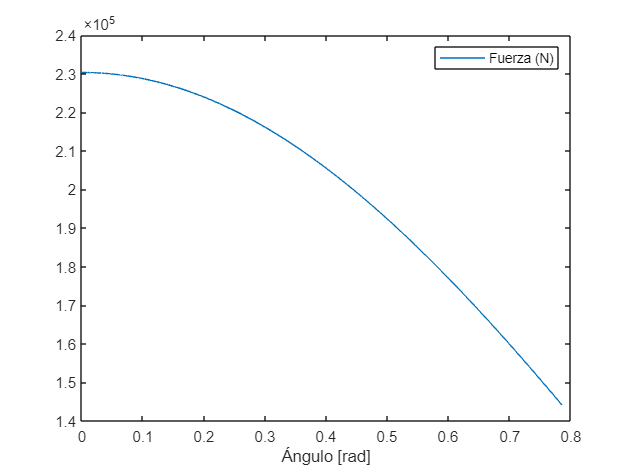


clc
clear all;

m=200;M=10000;d=3;g=9.8;

Z0=0*pi/180;Zp0=0;Zpp=.25;

Zf=45/180*pi;

Z=0; t=0; n=1;ti=0.001;
while Z<Zf

Zp=Zpp*t+Zp0;
Z=Zpp*t^2/2+Zp0*t+Z0;
A=8/3*m*d^2+4*M*d^2*(cos(Z))^2;
B=4*M*d^2*sin(Z)*cos(Z);
C=2*(M+m)*g*d*cos(Z);
D=d*cos(Z/2);
F=A/D*Zpp-B/D*Zp^2+C/D;
tt(n)=t;
ZZ(n)=Z; %vector ángulo
ZZp(n)=Zp; %vector velocidad angular
FF(n)=F;%vector Fuerza
v = 2*d*Zp*cos(Z);
y = 2*d*sin(Z); %Cálculo altura
p = Zp*d*F*cos(Z/2);
PP(n) = p;
VV(n) = v;
YY(n) = y;
t=t+ti;
n=n+1;
end

figure;
plot(ZZ,FF)
legend('Fuerza (N)')
xlabel('Ángulo [rad]')

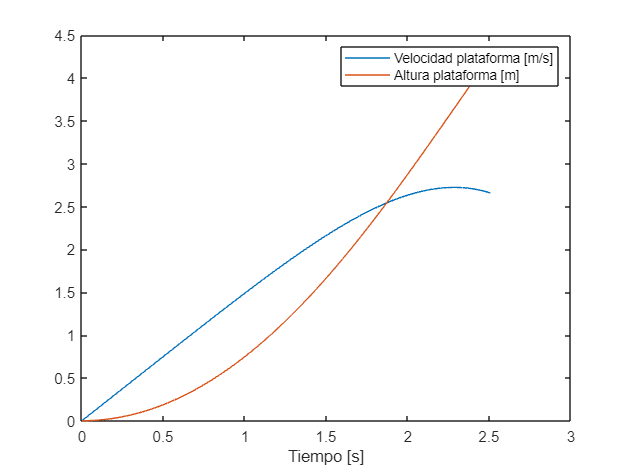


figure;
plot(tt,VV,tt,YY)
legend('Velocidad plataforma [m/s]', 'Altura plataforma [m]')
xlabel('Tiempo [s]')

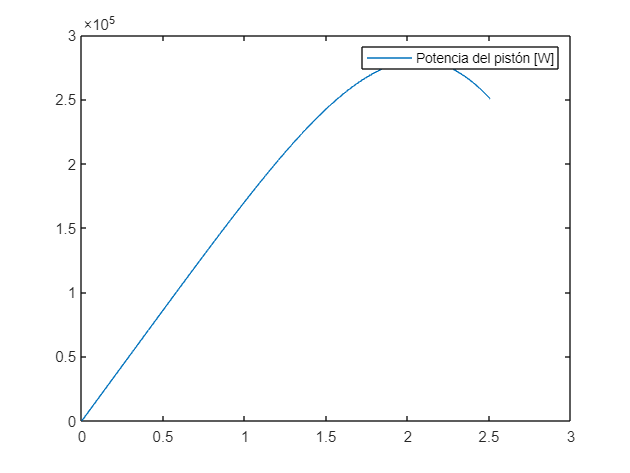


figure;
plot(tt,PP)
legend('Potencia del pistón [W]')


W = trapz(tt,PP)

W = 4.6047e+05